## **Przetwarzanie Sygnałów Cyfrowych**

# Próbkowanie sygnałów ciągłych 

## Jan Rosa 410269 AiR

### Ćwiczenie 1 

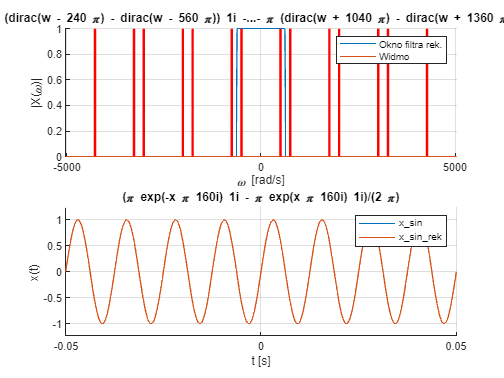

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

### Zadanie 2

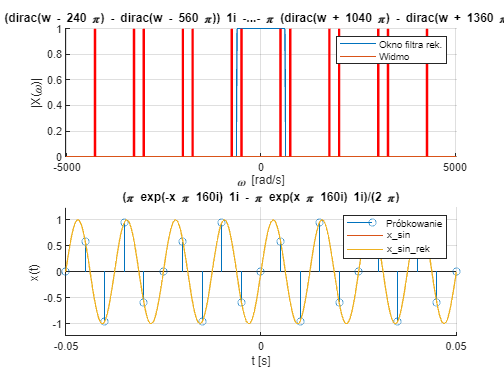

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');

### Zadanie 3

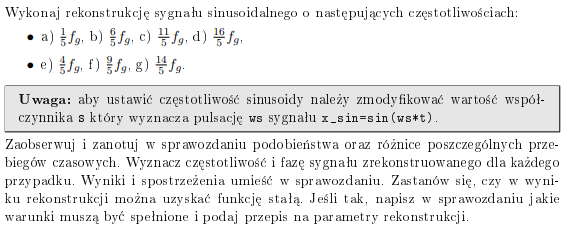

a)

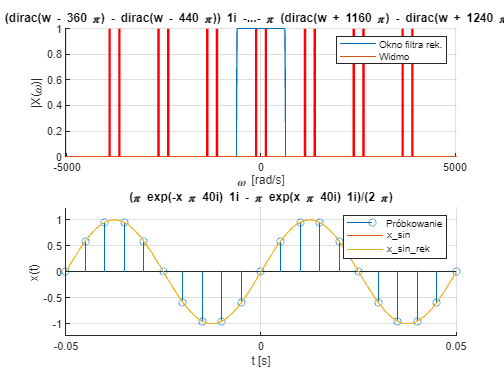

fgplot(1/5)

b)

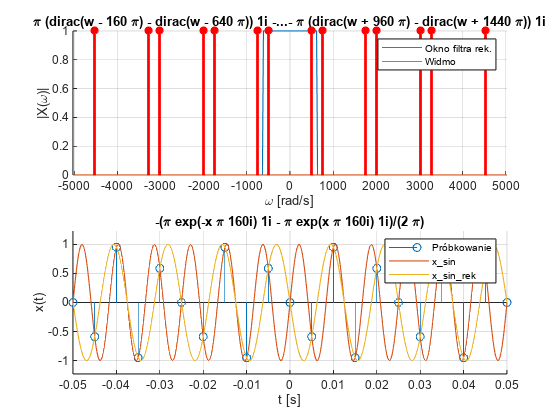

fgplot(6/5)

c)

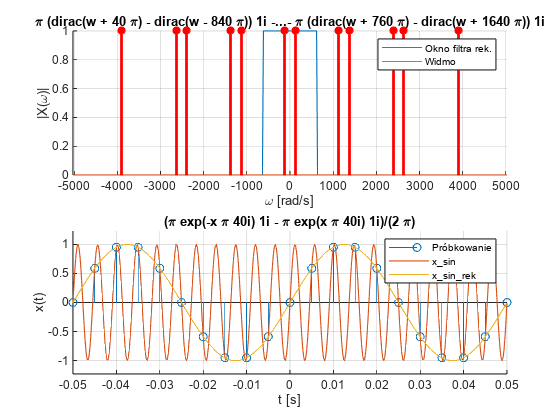

fgplot(11/5)

d)

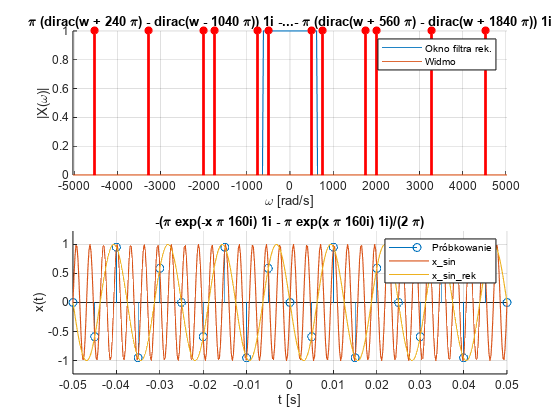

fgplot(16/5)

e)

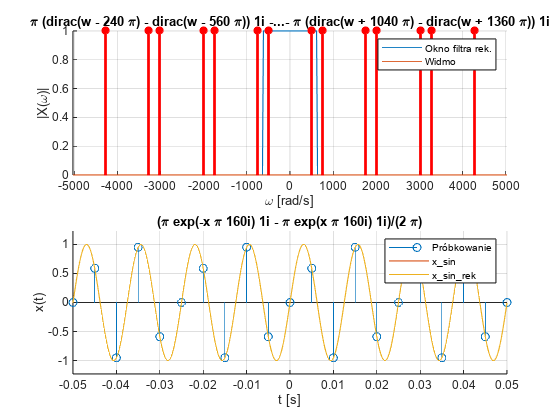

fgplot(4/5)

f)

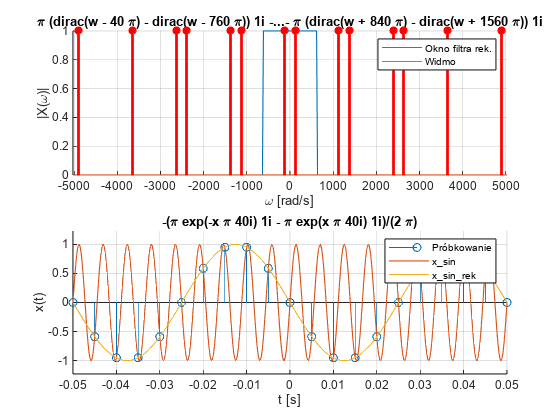

fgplot(9/5)

g)

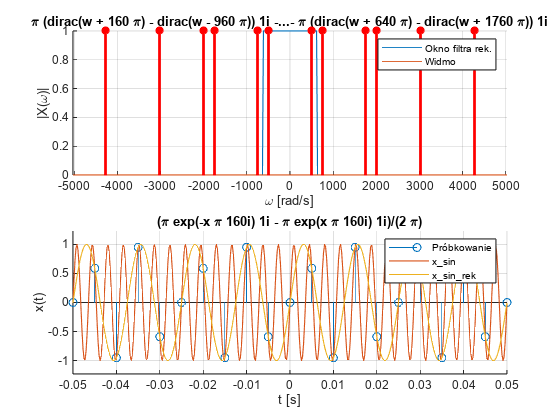

fgplot(14/5)

Funkcja jest stała wtedy gdy częstowliwość próbkownia pozostaje w stosunku 1/k do częstotliwości sygnału próbkowaniego gdzie k jest liczbą całkowitą.

### Zadanie 4

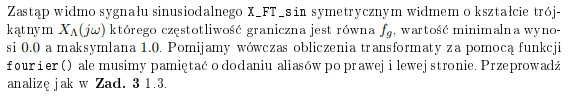

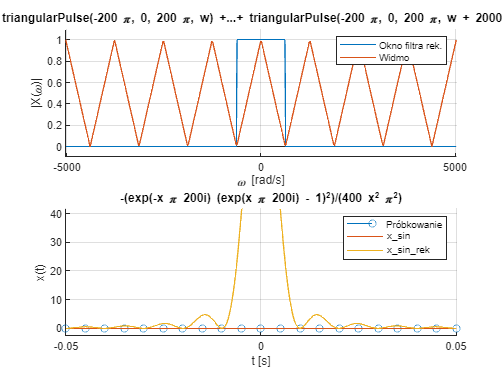

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sym(0);

X_FT_sin_org = triangularPulse(-wg, wg, w);
X_FT_sin = X_FT_sin_org + symsum((subs(X_FT_sin_org, w, w - K*wp ) + subs(X_FT_sin_org, w, w + K*wp)), K , 1, 5);
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
title("Trójkątnba transformata")
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
title('Rekonstukcja')
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');

### Zadanie 5

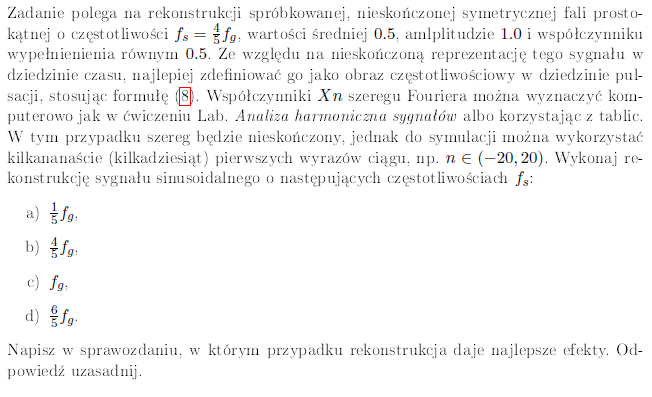

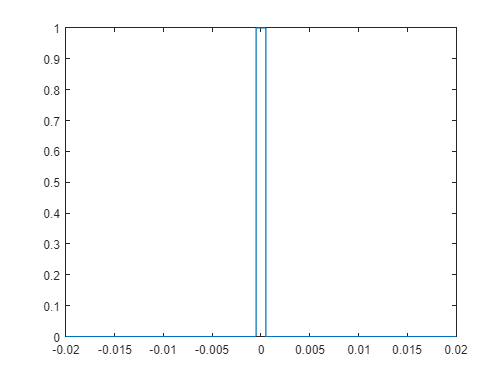

s = 1/5;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
Ts = s/fg;
x_sin = rectangularPulse(-Ts/4, Ts/4, t);

X_sin = x_sin + symsum(subs(x_sin, t, t - K/Ts ) + (subs(x_sin, t, t + K/Ts )), K , 1, 3);
figure
fplot(X_sin,[-0.02,0.02])

function [] = fgplot(s)
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');
end
